# Lab02 

## Creation of the grid

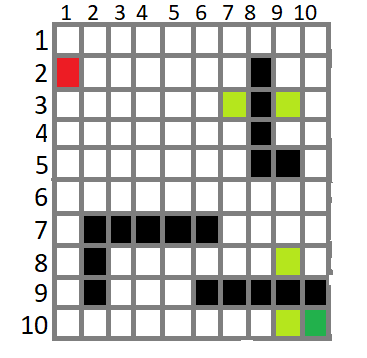

The black blocks represent obstacles.

The light green blocks represent the jumps.

The red blocks represent the start.

The dark green blocks represent the finish.

At first, we create our Grid by using the function createGridWorld.

Then, we say which is the current state (in our case, it is [2,1]) and which case is the terminal one ([10, 10]). After this, we determinate which cells are going to be the obstacles. We chose those cells because of the jump rules which were given. 

GW = createGridWorld(10,10)

GW =   GridWorld with properties:

          GridSize: [10 10]
      CurrentState: "[1,1]"
            States: [100×1 string]
           Actions: [4×1 string]
                 T: [100×100×4 double]
                 R: [100×100×4 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


GW.CurrentState = '[2,1]';
GW.TerminalStates = '[10,10]';
GW.ObstacleStates = ["[2,8]";"[3,8]";"[4,8]";"[5,8]";"[5,9]";"[9,6]";"[9,7]";"[9,8]";"[9,9]";"[9,10]";"[9,2]";"[8,2]";"[7,2]";"[7,3]";"[7,4]";"[7,5]";"[7,6]"];

Now, we need to set the jump rule. Here, it is that we cans jump from cell [3,7] to cell [3,9] and from cell [8,9] to [10,9]. 

updateStateTranstionForObstacles(GW)
GW.T(state2idx(GW,"[3,7]"),:,:) = 0;
GW.T(state2idx(GW,"[3,7]"),state2idx(GW,"[3,9]"),:) = 1;

GW.T(state2idx(GW,"[8,9]"),:,:) = 0;
GW.T(state2idx(GW,"[8,9]"),state2idx(GW,"[10,9]"),:) = 1;

We can now define the different rewards.

nS = numel(GW.States);
nA = numel(GW.Actions);
GW.R = -1*ones(nS,nS,nA);
GW.R(state2idx(GW,"[3,7]"),state2idx(GW,"[3,9]"),:) = 3;
GW.R(state2idx(GW,"[8,9]"),state2idx(GW,"[10,9]"),:) = 5;
GW.R(:,state2idx(GW,GW.TerminalStates),:) = 15;

In order to create the grid environment, we use `rlMDPEnv`

env = rlMDPEnv(GW)

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


Then we visualised the grid !

plot(env)

## Creation of the environment

As we said before, we want to start each time on the cell [2,1]. That is why we create a reset function that returns the state number for the initial agent state. This function is going to be called at each training episode and simulation. The anonymous function that we are going to create sets the initial state at 2.

env.ResetFcn = @() 2;

Now, we fix the random generator seed for reproductability.

rng('default')
rng(0)

## We create the Q-Learning Agent

Now, we have to create the Q-Learning Agent. 

First of all, in order to achieve this, we need to instantiate a Q table that contains the observations and actions that take place in our grid world environment. 

We also set the learning rate of the representation to 1.

qTable = rlTable(getObservationInfo(env),getActionInfo(env));
qRepresentation = rlQValueRepresentation(qTable,getObservationInfo(env),getActionInfo(env));
qRepresentation.Options.LearnRate = 1;

Thanks to the Q table and the representation, we can create the Q-Learning Agent. The Q-Learning Agent will allow us to estimate the future rewards.

We also have to configure de he epsilon-greedy exploration that will randomly select between the exploration and the exploitation 

agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .04;
qAgent = rlQAgent(qRepresentation,agentOpts);

## Training of the Q-Learning Agent

Now, to train the Q-Learning Agent, we are going to use some specific options.

We train our Agent for at most 300 episodes and in these episodes, you can have a maximum of 50 steps. We must also specify our training termination condition, we choose the AverageReward. It will stop learning when the current average reward is equal to or greater than the critical value. We set the critical value to 11 and we also specifies the window length for averaging rewards for each agent at 30 episodes.

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.MaxEpisodes= 300;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 11;
trainOpts.ScoreAveragingWindowLength = 30;

In order to train the agent, we use the function train. We set doTraining to True because we want to train the agent

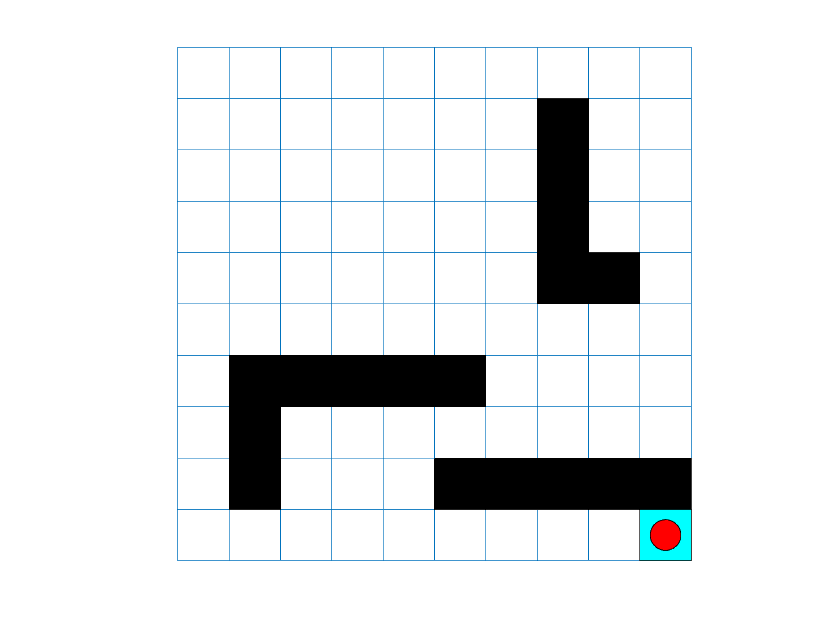

doTraining = true;

if doTraining
    % Train the agent.
trainingStats = train(qAgent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('basicGWQAgent.mat','qAgent')
end

## Validate Q-Learning Results

We will now display our agent training.  

We start by creating the environment to view the agent and set some options. We want to display the path the agent takes and clear it at the end of each trial.

plot(env)
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;

We can begin the simulation.

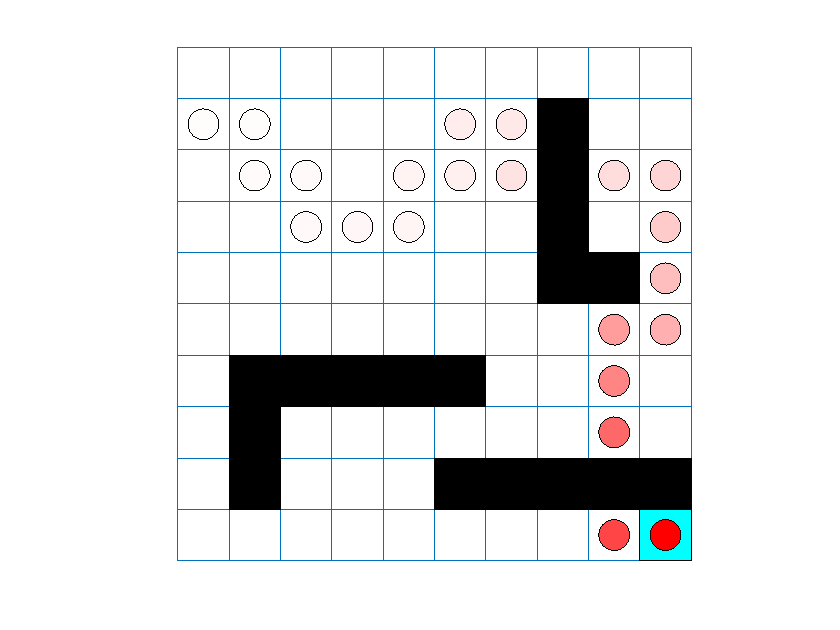

sim(qAgent,env)

## Create and Train SARSA Agent

We are going to use a SARSA Agent in our environnement.

We take the same Q Table representation and epsilon greedy configuration. 

agentOpts = rlSARSAAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = 0.04;
sarsaAgent = rlSARSAAgent(qRepresentation,agentOpts);

The SARSA Agent and the Q-Learning Agent are trained in the same way. 

doTraining = false;

if doTraining
    % Train the agent.
    trainingStats = train(sarsaAgent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('basicGWSarsaAgent.mat','sarsaAgent')
end

## Validate SARSA Training

To display our SARSA Agent training, we use the same environment as above.

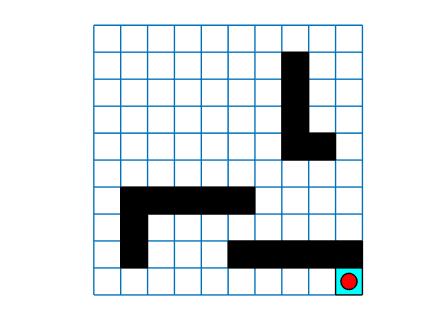

plot(env)

env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;
sim(sarsaAgent,env)

Error using rl.util.validateAgentsWithEnv>localValidateForSim (line 69)
Observation info of environment and agent is different.

Error in rl.util.validateAgentsWithEnv (line 23)
        localValidateForSim(agents,env);

Error in 